clc;
close all;
clear variables;

## Creating a datastore for my images

folder_name = fullfile(pwd, 'data');
imds = imageDatastore(folder_name, 'LabelSource',"foldernames");


### Label data 

Get label from filename

imds.Labels = char(imds.Labels); % turn labes to char
N = length(imds.Files);
for i = 1:N
    filename = imds.Files{i}(length(folder_name) + 1:end);
    left_parenth_index = find(filename == ' ');
    label = filename(2:left_parenth_index - 1);
    if strcmp(label, 'prazna')
        label = 'E';
    elseif strcmp(label,'pune')
        label = 'F';
    end
    imds.Labels{i} = label;
end

### Display raw images

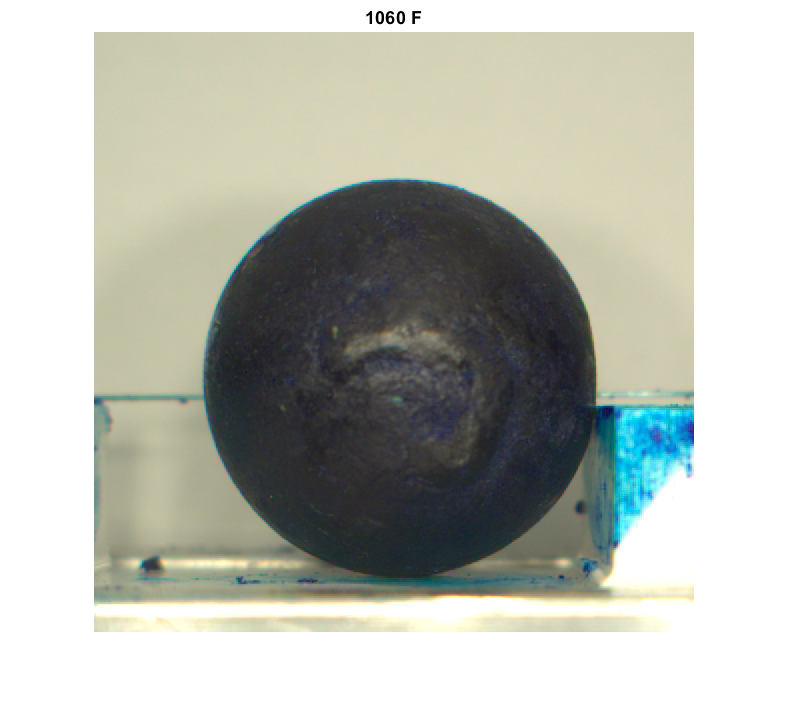

for i=1:1
    figure();
    rand_int = randi(length(imds.Files));
    imshow(readimage(imds, rand_int))
    title(rand_int + " " + imds.Labels{rand_int})
end

## Preprocessing images

target_size = [600, 600];
final_size = [200, 200];

preprocessed_imds = transform(imds, @(x) imresize(x, target_size));

Downsample images for easier computation

preprocessed_imds = transform(preprocessed_imds, @(x) imresize(x, final_size));


### Display preprocessed images

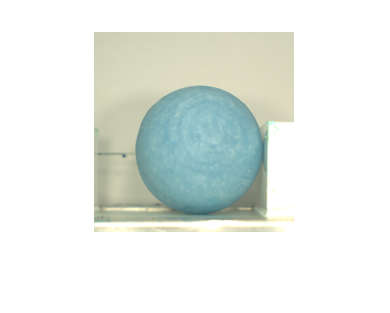

for i=1:1
    preprocessed_imds = shuffle(preprocessed_imds);
    figure();
    I = preview(preprocessed_imds);
    imshow(I)
end

## Feature extraction

figure('Position', [10 10 900 600]);
imshow(I);
hold on

% hog surf and kaze are good for classification apparently
% https://www.mathworks.com/help/vision/ug/local-feature-detection-and-extraction.html

HOG, surf and kaze are good for classification apparently.

[https://www.mathworks.com/help/vision/ug/local-feature-detection-and-extraction.html](https://www.mathworks.com/help/vision/ug/local-feature-detection-and-extraction.html)

method_name = "hog";
num_points = 10;
cell_size = [25, 25];


Histogram of oriented gradients

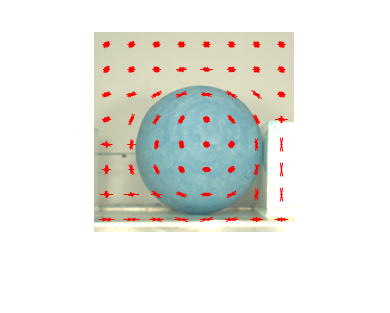

if method_name == "hog"
    [featureVector, visualization] = extractHOGFeatures(I,'CellSize',cell_size);
    plot(visualization, 'Color','red')
end
hold off

### Extract features

if method_name == "hog"
    features_ds = transform(preprocessed_imds, @(x) extractHOGFeatures(x, 'CellSize',cell_size));
end


data = double(readall(features_ds));

### Dimensionality reduction

### Principal component analysis

[coeff,~,~,~,explained,~] = pca(data);

% of info contained in each coordinate

explained

explained =    21.5843
   12.9228
    6.7476
    5.7768
    4.7817
    3.4392
    2.1800
    1.6714
    1.5305
    1.3324


feature_vector_size = 20; % less is more?

% of info contained in the chosen *feature_vector_size* coordinates

sum(explained(1:feature_vector_size))

ans = 70.8951

A_dim_reduction = coeff(:, 1:feature_vector_size);

Data times chosen eigenvectors matrix

features_ds = transform(features_ds, @(x) x * A_dim_reduction);
data_low_dim = double(readall(features_ds));

## Dividing the dataset

split_ratio = 0.7;

all_labels = features_ds.UnderlyingDatastore.Labels;

[training, testing] = divide_dataset(data_low_dim, all_labels, split_ratio, features_ds)

training =   MyDataset with properties:

        labels: {1×764 cell}
          data: [764×20 double]
    file_names: {1×764 cell}


testing =   MyDataset with properties:

        labels: {1×328 cell}
          data: [328×20 double]
    file_names: {1×328 cell}


## Classification

Conduct Bayes' test

training_classes = distribution_parameters(training);
test_result = cell(length(testing.labels), 1);

for i = 1:length(testing.labels)
   test_result{i} = char(bayes_test_least_error(testing.data(i, :), training_classes));
end

Calculate and plot confusion matrix

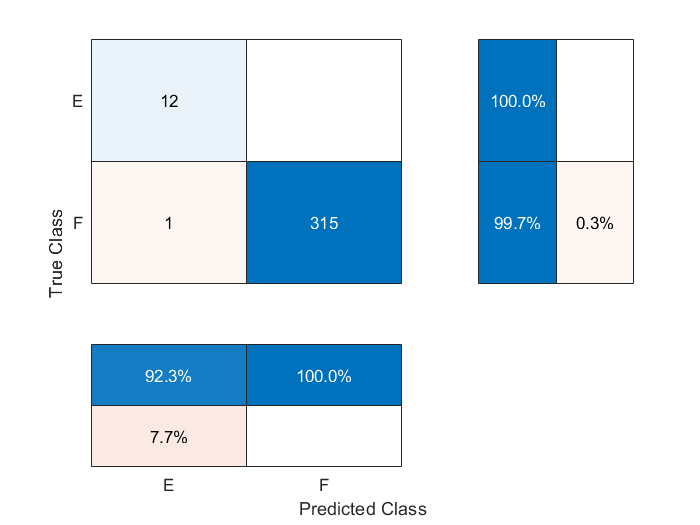

conf_mat = confusionmat(testing.labels, test_result);

figure();
cm = confusionchart(conf_mat, unique(all_labels), "ColumnSummary","column-normalized", 'RowSummary',"row-normalized");

incorrect_indices = find([testing.labels{:}] ~= [test_result{:}]);
incorrectly_classified_files = testing.file_names(incorrect_indices)'

incorrectly_classified_files = 1×1 cell array
    {'C:\Users\HP\Desktop\Faks\Matlab\Predmeti\Prepoznavanje oblika\Glavni domaci\Assignment 3\data\pune (388).bmp'}


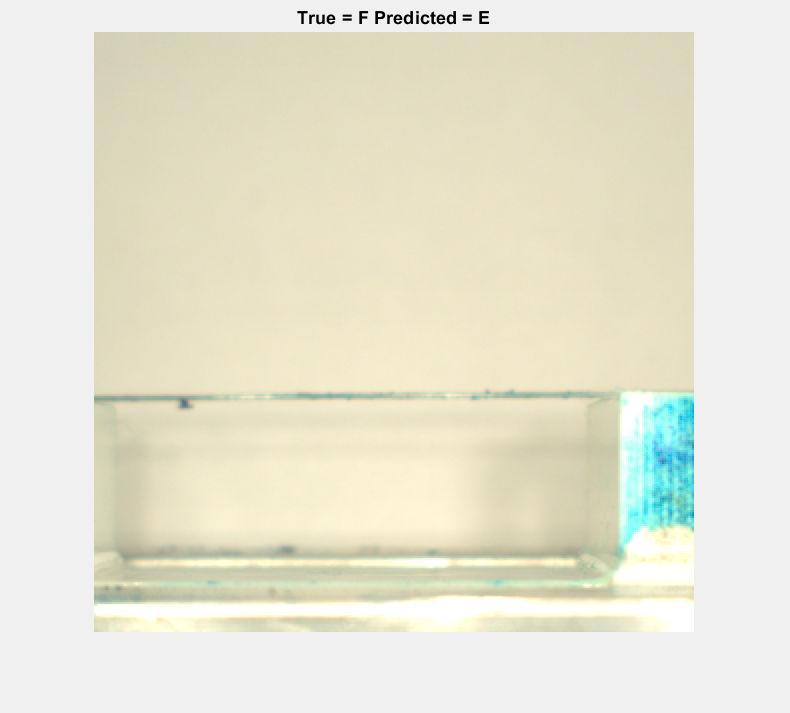


for i = 1:length(incorrectly_classified_files)
    figure();
    set(gcf,'Visible','on')
    I = imread(incorrectly_classified_files{i});
    imshow(I)
    title("True = " + testing.labels{incorrect_indices(i)} + " Predicted = " + test_result{incorrect_indices(i)})
end

## Classifiy whole dataset

split_ratio = 0.0;

all_labels = features_ds.UnderlyingDatastore.Labels;

[~, testing] = divide_dataset(data_low_dim, all_labels, split_ratio, features_ds)

testing =   MyDataset with properties:

        labels: {1×1092 cell}
          data: [1092×20 double]
    file_names: {1×1092 cell}


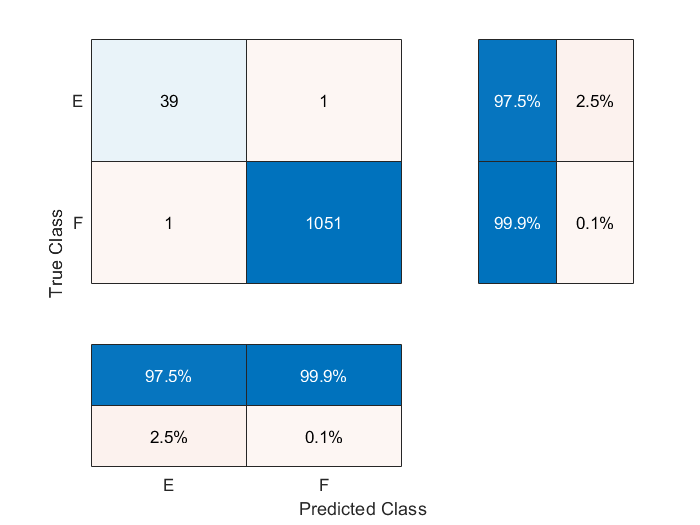

test_result = cell(length(testing.labels), 1);

for i = 1:length(testing.labels)
   test_result{i} = char(bayes_test_least_error(testing.data(i, :), training_classes));
end

conf_mat = confusionmat(testing.labels, test_result);

figure()
cm = confusionchart(conf_mat, unique(all_labels), "ColumnSummary","column-normalized", 'RowSummary',"row-normalized");